# Using Casadi for Collision Avoidance OCP

This is a re-implementation of ex1_static_obstacle with a new vehicle-tire model (9-state, more realistic).

The vehicle body is a 3DOF planar body, the tire model is a smoothed Dugoff model (see Draft 2 for details).

Some ideas on debugging Casadi/IPOPT solver failure:

- Tune (increase) the problem discretization level;

- Soften the constraints (especially the dynamic equality constraints) by adding a slack variable;

- Use the closest feasible solution (or failed infeasible solution) to re-calculate the objective function and see if there's anything fishy;

Debug insights:

- For the IPOPT solver, the inf_du value does not go down much (stays at the ~1e3 level). This is concerning because the usual tolerance for inf_pr and inf_du are about ~1e-6 or lower. This indicates that the solver thinks it cannot find a solution feasible enough. We may want to cross check this, by looking at what a "good" solution's inf_pr and inf_du looks like, then go from there to gradually "warm-start" towards the current place.

addpath('C:\Program Files\casadi-windows-matlabR2016a-v3.5.5');
import casadi.*

clear sol;
OCP = colliOCPv2(10);
OCP.build_basics();
OCP.zero_objective();

Zero objective function applied!


% manually change the collision criteria
OCP.R_col = 2.00; % collision radius (larger than 2 to fit the ziegler circle definition)
OCP.build_debug_var(); % for debug, run this function
OCP.add_control_bounds(); % use default bounds
% OCP.add_initial_conditions(); % use default I.C.'s
% v_xb0 = 3; v_yb0 = 0; px0 = 0; py0 = 5; r0 = 0; psi0 = 0; omega_f0 = 10; omega_r0 = 10; delta0 = 0;
v_xb0 = 3; v_yb0 = -1; px0 = 0; py0 = 5; r0 = 0; psi0 = 0; omega_f0 = 10; omega_r0 = 10; delta0 = 0;
OCP.add_initial_conditions(v_xb0,v_yb0,px0,py0,r0,psi0,omega_f0,omega_r0,delta0); % driving straight
% OCP.add_initial_conditions(5,0,0,5,5,0,30,30,0); % initially spinning
OCP.add_path_constraints(); % use default constraints
OCP.add_ego_centers();
OCP.add_obstacle_centers(); % use default static obstacle
OCP.add_collision_constraint();
OCP.add_terminal_conditions(); % default T.C.'s
% OCP.modify_objective(); % add obstacle CG repulsion into the objective.
OCP.set_solver_init();
% OCP.warm_start_init(sol);
% solver options
% plugin_opts = struct('print_time',false);
% solver_opts = struct('max_iter',50,'print_level',0);
plugin_opts = struct('print_time',true);
solver_opts = struct('max_iter',2000,'hessian_approximation','limited-memory','tol',1e-4);
sol = OCP.solve(plugin_opts,solver_opts);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:      859
Number of nonzeros in inequality constraint Jacobian.:      317
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:      119
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:       99
Total number of inequality constraints...............:      152
        inequality constraints with only lower bounds:       99
   inequality constraints with lower and upper bounds:       53
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

Error using casadi.Opti/solve
Error in Opti::solve [OptiNode] at .../casadi/core/optistack.cpp:159:
.../casadi/core/optistack_internal.cpp:999: Assertion
"return_success(accept_limit)" failed:
Solver failed. You may use opti.debug.value to investigate the latest values of
variables. return_status is 'Maximum_Iterations_Exceeded'

Error in colliOCPv2/solve (line 506)
            sol = obj.opti.solve();   % actual solve

if ~exist('sol','var')
    foundSol = false
    sol = OCP.opti.debug;
else
    foundSol = true
end

foundSol = logical
   0


If the solver has a solution, we can visualize the states, intermediate variables, controls.

If the solver failed, we can still use opti.debug.value() to investigate the values of variables.

% if solutin is found, set foundSol = true. Otherwise set foundSol = false, and 
% the debug results will be used instead.
[obj_func_val,modified_obj_func_val] = calculate_cost(OCP,sol,foundSol)
pp.basic_plots_dugoff(OCP,sol);
pp.controls_plot_dugoff(OCP,sol)
debug_plot(OCP,sol,foundSol)

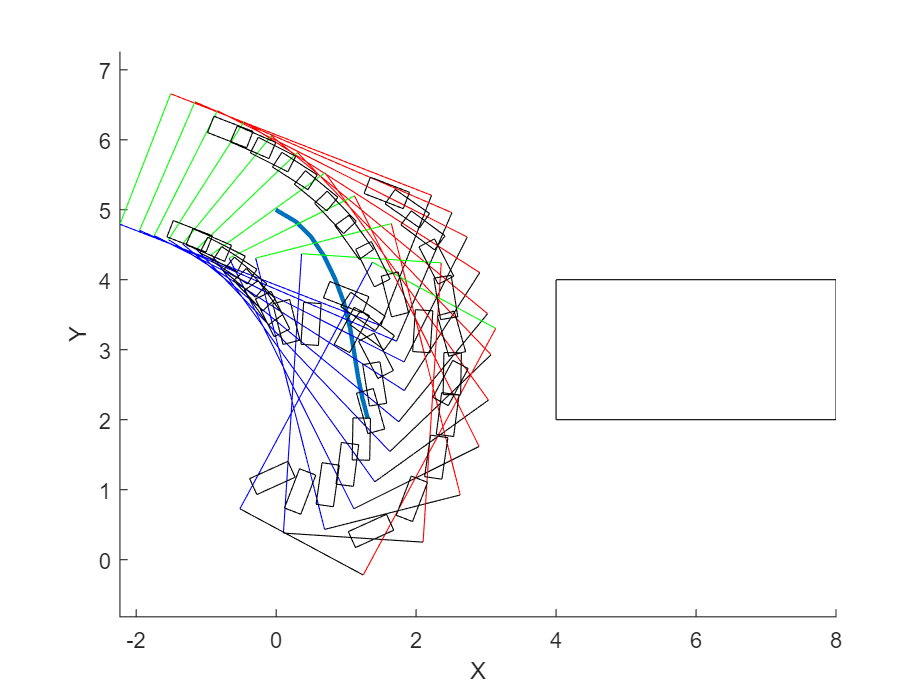

pp.rectangle_overlap(OCP,sol);

Use the 3-circle representation:

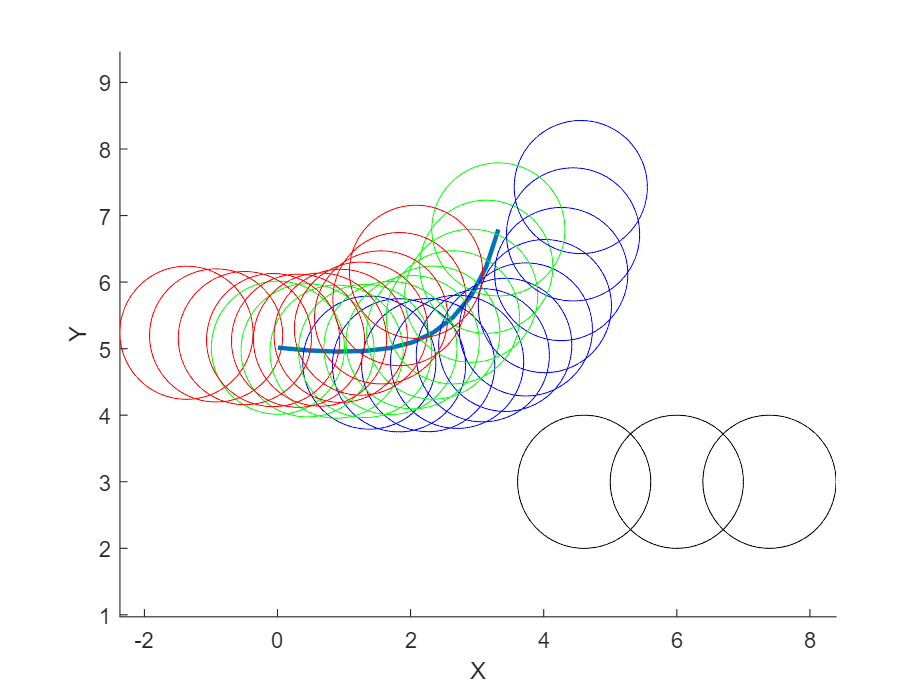

pp.circles_overlap(OCP,sol);

Make a video

videoName = 'linear_tire_static_obstacle';
pp.make_video_rectangles(OCP,sol,videoName,foundSol)

Plot the Jacobian and the Hessian

figure
spy(sol.value(jacobian(OCP.opti.g,OCP.opti.x)))
figure
spy(sol.value(hessian(OCP.opti.f+OCP.opti.lam_g'*OCP.opti.g,OCP.opti.x)))

Helper functions (you may want to group these helper functions into a class later)

function [cost,modified_cost] = calculate_cost(OCP,sol,foundSol)
    %calculate_cost Calculate the cost (objective) function value
    if ~foundSol
        sol = OCP.opti.debug;
    end

    cost = sum(sol.value((OCP.tau/1000).^2 + OCP.nu.^2));

    modified_cost = -sum(sol.value((OCP.px(2:end) - OCP.x_b).^2 ...
        + (OCP.py(2:end) - OCP.y_b).^2));
end



function debug_plot(OCP,sol,foundSol)
    %debug_plot Plot the debug signals
    if ~foundSol
        sol = OCP.opti.debug;
    end
    figure('Position',[100 100 800 1200]);
    tiledlayout(6,2)
    nexttile;
    hold on
    plot(sol.value(OCP.v_xb_dbg),'LineWidth',2);
    plot(sol.value(OCP.v_yb_dbg),'LineWidth',2);
    legend('$v_{xb}$','$v_{yb}$','interpreter','latex');
    title('Ego velocity in Body Frame')
    nexttile;
    hold on
    plot(sol.value(OCP.V_xft_dbg),'LineWidth',2);
    plot(sol.value(OCP.V_xrt_dbg),'LineWidth',2);
    legend('$v_{xft}$','$v_{xrt}$','interpreter','latex')
    title('Longitudinal Velocity in Tire Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.kappa_f_dbg),'LineWidth',2);
    plot(sol.value(OCP.kappa_r_dbg),'LineWidth',2);
    legend('$\kappa_{f}$','$\kappa_{r}$','interpreter','latex');
    title('Longitudinal Tire Slip Ratio')
    nexttile;
    hold on
    plot(sol.value(OCP.alpha_f_dbg),'LineWidth',2);
    plot(sol.value(OCP.alpha_r_dbg),'LineWidth',2);
    legend('$\alpha_{f}$','$\alpha_{r}$','interpreter','latex');
    title('Lateral Tire Slip Angle')
    nexttile;
    hold on
    plot(sol.value(OCP.F_zf_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_zr_dbg),'LineWidth',2);
    legend('$F_{zf}$','$F_{zr}$','interpreter','latex');
    title('Vertical Axle Load')
    nexttile;
    hold on
    plot(sol.value(OCP.flambda_f_dbg),'LineWidth',2);
    plot(sol.value(OCP.flambda_r_dbg),'LineWidth',2);
    legend('$f(\lambda_{f})$','$f(\lambda_{r})$','interpreter','latex');
    title('F(Lambda)');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xft_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yft_dbg),'LineWidth',2);
    legend('$F_{xft}$','$F_{yft}$','interpreter','latex');
    title('Front Tire Force in Tire Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xrt_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yrt_dbg),'LineWidth',2);
    legend('$F_{xrt}$','$F_{yrt}$','interpreter','latex');
    title('Rear Tire Force in Tire Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xfb_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yfb_dbg),'LineWidth',2);
    legend('$F_{xfb}$','$F_{yfb}$','interpreter','latex');
    title('Front Axle Force in Body Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xrb_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yrb_dbg),'LineWidth',2);
    legend('$F_{xrb}$','$F_{yrb}$','interpreter','latex');
    title('Rear Axle Force in Body Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xf_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yf_dbg),'LineWidth',2);
    legend('$F_{xf}$','$F_{yf}$','interpreter','latex');
    title('Front Axle Force in Global Frame');
    nexttile;
    hold on
    plot(sol.value(OCP.F_xr_dbg),'LineWidth',2);
    plot(sol.value(OCP.F_yr_dbg),'LineWidth',2);
    legend('$F_{xr}$','$F_{yr}$','interpreter','latex');
    title('Rear Axle Force in Global Frame');
end